## **Driver test program to check Clothoids library**

**Biarcs**

Biarc data as Hermite data (point+tangent) and as point direction (MATLAB format)

x0=-1; y0=0; x1=1; y1=0;
theta0 = pi/12;
theta1 = -pi/4;
a0     = theta0+pi/2;
a1     = theta1+pi/2;

p =[x0,x1;y0,y1];
u =[cos(a0),cos(a1);sin(a0),sin(a1)];

Build and plot matlab biarc

subplot(2,1,1);
hold off
plot(p(1,:),p(2,:),'k');
hold on
bi_arc = fnrfn(rscvn(p,u),[0.5,1.5]);
bspline_plot(bi_arc,true);
axis equal;

Build and plot biarc of Clothoids library

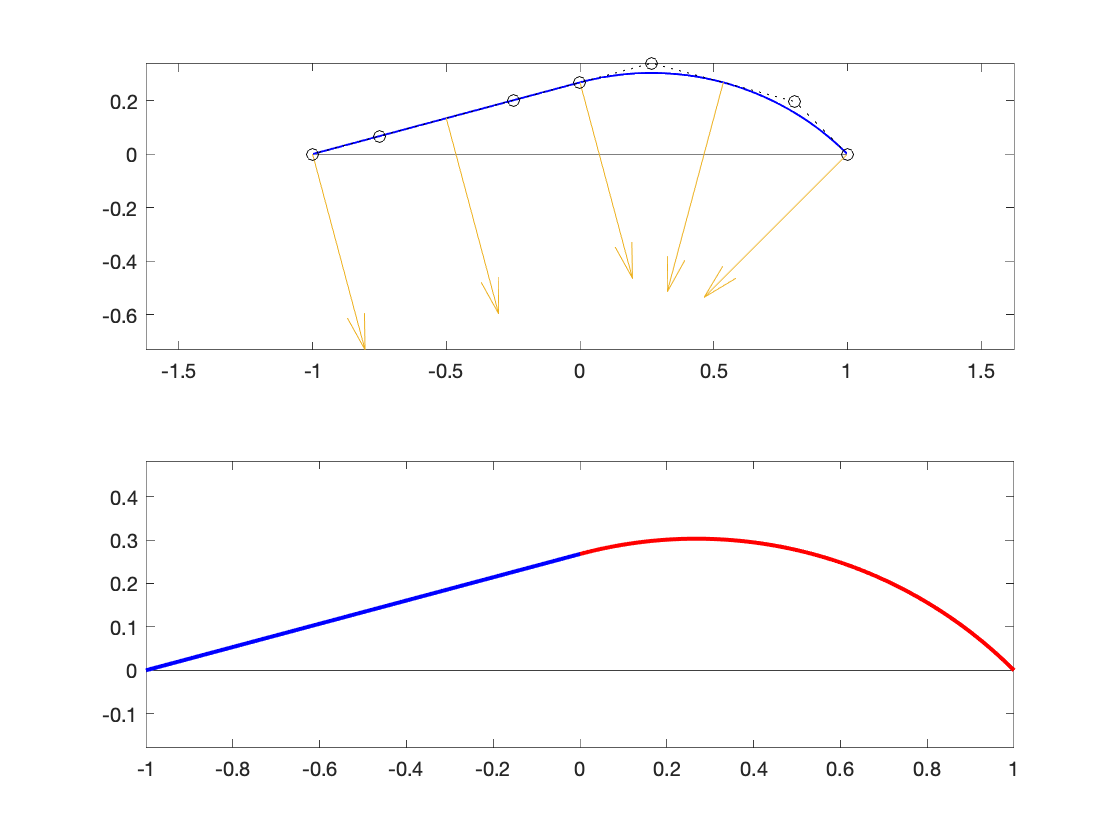

subplot(2,1,2);
hold off
plot(p(1,:),p(2,:),'k');
hold on
L1 = Biarc(x0,y0,theta0,x1,y1,theta1);

L1.plot();
axis equal

L1.info();

BiArc
C0
x0     = -1
y0     = 0
theta0 = 0.261799
k      = 5.36197e-17
L      = 1.03528
C1
x0     = 0
y0     = 0.267949
theta0 = 0.261799
k      = -0.965926
L      = 1.08414


